%% Hu RIBOmap tissue test

run_id = 'max';

input_path = 'Z:/Data/Processed/2021-11-23-Hu-MouseBrainSTARmap-test/';

input_dim = [2048 2048 35 4 9]; % ignore 5th channel

useGPU = false;

curr_data_dir = 'Position157';
curr_out_path = fullfile(input_path, 'output', run_id, curr_data_dir);

if ~exist(curr_out_path, 'dir')
    mkdir(curr_out_path)
end

curr_img_out_path = fullfile(input_path, 'output', run_id, 'dots_image');

if ~exist(curr_img_out_path, 'dir')
    mkdir(curr_img_out_path)
end

sdata_start = tic;
sdata = new_STARMapDataset(input_path, 'useGPU', useGPU);

Pipeline Obj is generated...


sdata.log = fopen(fullfile(curr_out_path, 'log.txt'), 'w');
fprintf(sdata.log, sprintf("====Current Position: %s====\n", curr_data_dir));
sdata = sdata.LoadRawImages('sub_dir', curr_data_dir, 'input_dim', input_dim);

====Loading raw images====
Loading round 1...[time = 13.40 s]
Loading round 2...[time = 14.07 s]
Loading round 3...[time = 14.11 s]
Loading round 4...[time = 13.41 s]
Loading round 5...[time = 13.82 s]
Loading round 6...[time = 16.11 s]
Loading round 7...[time = 13.66 s]
Loading round 8...[time = 13.97 s]
Loading round 9...[time = 14.17 s]
Raw image as 5-D array


sdata = sdata.SwapChannels;

====Swap Channels====
Channel 2 <==> Channel 3


sdata = sdata.MinMaxNormalize;

====Min-Max intensity normalization====
Normalizing Round 1...[time = 6.15 s]
Normalizing Round 2...[time = 3.97 s]
Normalizing Round 3...[time = 3.93 s]
Normalizing Round 4...[time = 3.89 s]
Normalizing Round 5...[time = 3.98 s]
Normalizing Round 6...[time = 3.94 s]
Normalizing Round 7...[time = 3.88 s]
Normalizing Round 8...[time = 3.77 s]
Normalizing Round 9...[time = 3.70 s]


sdata = sdata.HistEqualize('Method', "inter_round");

====Histogram Equalization====
Method: inter_round
Equalizing channel 1
Equalizing channel 2
Equalizing channel 3
Equalizing channel 4


sdata = sdata.HistEqualize('Method', "intra_round");

====Histogram Equalization====
Method: intra_round
Equalizing round 1
Equalizing round 2
Equalizing round 3
Equalizing round 4
Equalizing round 5
Equalizing round 6
Equalizing round 7
Equalizing round 8
Equalizing round 9


sdata = sdata.MorphoRecon('Method', "2d", 'radius', 6);

====Morphological Reconstruction====
Method: 2d
Processing Round 1...[time = 14.23 s]
Processing Round 2...[time = 11.31 s]
Processing Round 3...[time = 11.03 s]
Processing Round 4...[time = 11.27 s]
Processing Round 5...[time = 11.50 s]
Processing Round 6...[time = 11.35 s]
Processing Round 7...[time = 11.60 s]
Processing Round 8...[time = 11.69 s]
Processing Round 9...[time = 11.33 s]


sdata = sdata.test_GlobalRegistration('useGPU', false);

====Global Registration====
DFT register finished [time=8.526319]
DFT apply finished [time=31.520377]
Round 2 vs. Round 1 finished [time=40.423494]
Shifted by 42  48   1
DFT register finished [time=8.983777]
DFT apply finished [time=30.747955]
Round 3 vs. Round 1 finished [time=40.101381]
Shifted by 56  60   3
DFT register finished [time=8.652859]
DFT apply finished [time=30.775510]
Round 4 vs. Round 1 finished [time=39.801195]
Shifted by 10   4   3
DFT register finished [time=8.587648]
DFT apply finished [time=30.544607]
Round 5 vs. Round 1 finished [time=39.519871]
Shifted by 7  1  2
DFT register finished [time=8.762597]
DFT apply finished [time=30.637834]
Round 6 vs. Round 1 finished [time=39.775067]
Shifted by 7  0  3
DFT register finished [time=8.861465]
DFT apply finished [time=30.183454]
Round 7 vs. Round 1 finished [time=39.424276]
Shifted by 7  1  1
DFT register finished [time=8.564259]
DFT apply finished [time=30.440099]
Round 8 vs. Round 1 finished [time=39.379507]
Shifted b

sdata = sdata.LocalRegistration('Iterations', 50, 'AccumulatedFieldSmoothing', 1);

====Local (Non-rigid) Registration====
[time = 0.00 s]
Round 2 vs. Round 1...[time = 1990.56 s]
Round 3 vs. Round 1...[time = 1961.40 s]
Round 4 vs. Round 1...[time = 1978.75 s]
Round 5 vs. Round 1...[time = 1980.55 s]
Round 6 vs. Round 1...[time = 1979.56 s]
Round 7 vs. Round 1...[time = 2036.59 s]
Round 8 vs. Round 1...[time = 1966.20 s]
Round 9 vs. Round 1...[time = 2117.82 s]


sdata = sdata.LoadCodebook('remove_index', 5);

====Load Codebook====
doReverse: 1


sdata = sdata.SpotFinding('Method', "max3d", 'ref_index', 1, 'showPlots', false);

====Spot Finding====
Method: max3d
Reference round: 1
Number of spots found by max3d: 157157
[time = 118.92 s]


sdata = sdata.ReadsExtraction('voxelSize', [1 1 1]);

====Reads Extraction====
voxel size: 1 x 1 x 1
Geting color sequence for each voxel...

Geting max color...
43565 
Decoding...
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).

Number of spots were dropped because of multi-max color: 43565


sdata = sdata.ReadsFiltration('mode', "duo", 'endBases', ['C', 'T'], 'split_loc', 5, 'showPlots', false);

====Reads Filtration====
mode: duo
Base in both ends: C --- T
1.000000 [113592 / 113592] percent of reads are below score thresh 5.000000e-01
Filtration Statistics:
0.279315 [31728 / 113592] percent of good reads match barcode pattern CN..NC - TN..NT
0.241161 [27394 / 113592] percent of good reads are in codebook
0.863401 [27394 / 31728] percent of form matched reads are in codebook



%     % Save registered image
%     output_dir = fullfile(curr_out_path, 'registered_image');
%     if ~exist(output_dir, 'dir')
%        mkdir(output_dir);
%     end
%     new_SaveImg(output_dir, sdata.registeredImages);

% Save round 1 image
output_dir = fullfile(input_path, 'output', run_id, 'round1_merged');
if ~exist(output_dir, 'dir')
   mkdir(output_dir);
end
r1_img = max(sdata.registeredImages(:,:,:,:,1), [], 4);
r1_img_name = fullfile(output_dir, sprintf("%s.tif", curr_data_dir));
SaveSingleTiff(r1_img, r1_img_name)

% Save points (allSpots)
allSpots = sdata.allSpots;
allReads = sdata.allReads;

save(fullfile(curr_out_path, strcat('allPoints_max3d.mat')), 'allReads', 'allSpots');


% Save points (goodSpots)
goodSpots = sdata.goodSpots;
goodReads = sdata.goodReads;

save(fullfile(curr_out_path, strcat('goodPoints_max3d.mat')), 'goodReads', 'goodSpots');

fprintf(sprintf("====%s Finished [time=%02f]====", curr_data_dir, toc(sdata_start)));

====Position157 Finished [time=16886.338957]====

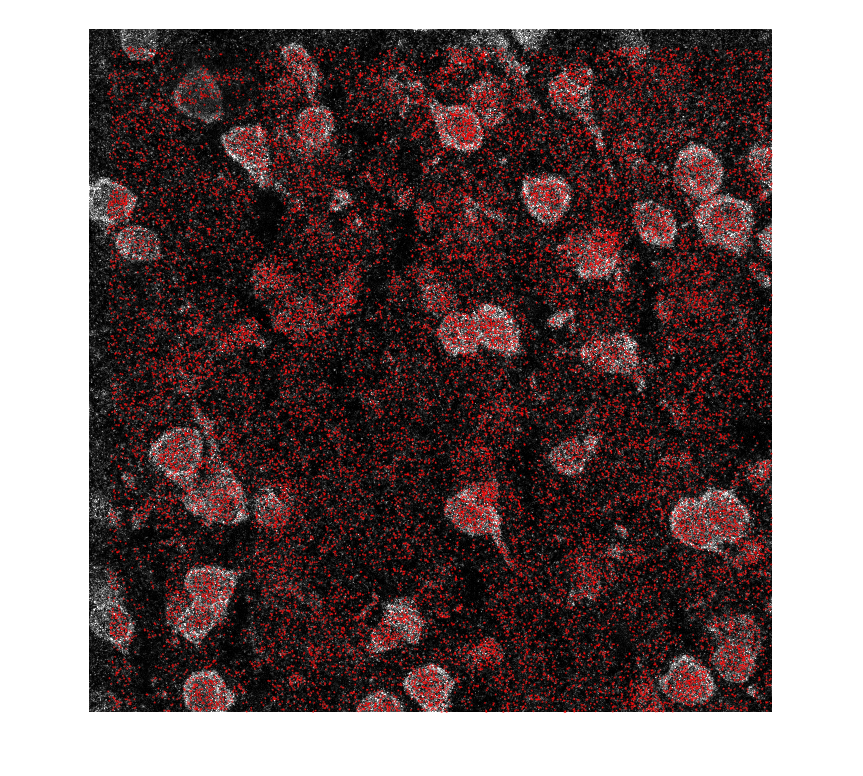

fprintf(sdata.log, sprintf("====%s Finished [time=%02f]====", curr_data_dir, toc(sdata_start)));

% Save dots image
curr_img = max(sdata.registeredImages(:,:,:,:,1), [], 4);
curr_img = max(curr_img, [], 3);

if ~isempty(goodSpots)
    plot_centroids(goodSpots, curr_img, 2, 'r')
    saveas(gcf, fullfile(curr_img_out_path, sprintf("%s.tif", curr_data_dir)));
end


fclose(sdata.log);
